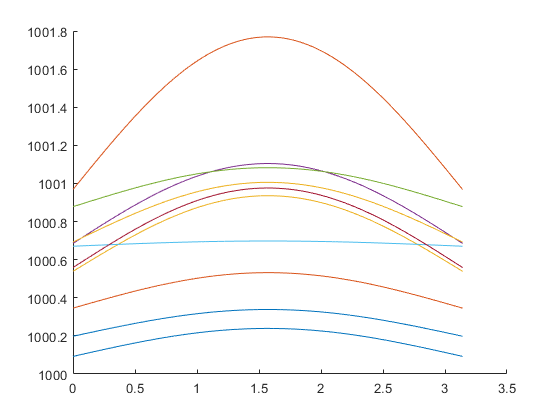

clear; close all;

N_res = 10;

N_res_h = 1000; [xh,~] = get_rand_data(N_res_h);

N_samp = 1000;

sigma = 1e-4;

figure()
hold on
for i = 1:10
    [x,y] = get_rand_data(N_res_h);
    plot(x,y)
end


[kfcn,C] = get_kfcn(N_samp,N_res_h);

% hfcn = get_hfcn();

% figure()
% imagesc(C)
% colorbar
% title('original covariance')
% 
% figure()
% [x_temp,~] = get_rand_data(N_res);
% imagesc(kfcn(x_temp,x_temp))
% colorbar
% title('interp covariance')

rng(1)
[x,y] = get_rand_data(N_res);

figure()
hold on
scatter(x,y)
modelml = fit_matlab_model(x,y,sigma,kfcn)

modelml =   RegressionGP
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 10
           KernelFunction: @(xi,xj,dummy)interp2(x,x',C,xi,xj')'
        KernelInformation: [1×1 struct]
            BasisFunction: 'Constant'
                     Beta: 1.0007e+03
                    Sigma: 0.0016
        PredictorLocation: []
           PredictorScale: []
                    Alpha: [10×1 double]
         ActiveSetVectors: [10×1 double]
            PredictMethod: 'Exact'
            ActiveSetSize: 10
                FitMethod: 'Exact'
          ActiveSetMethod: 'Random'
        IsActiveSetVector: [10×1 logical]
            LogLikelihood: 42.5794
         ActiveSetHistory: []
           BCDInformation: []


  Properties, Methods


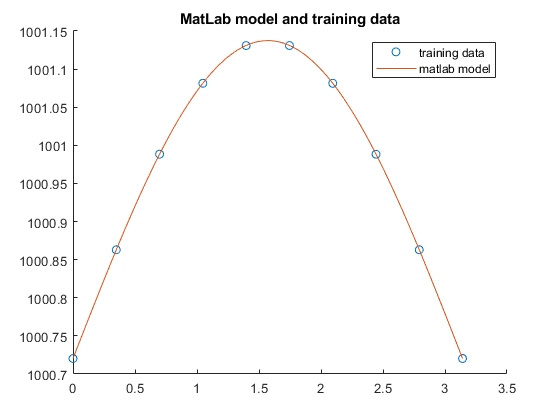

ypredml = predict(modelml,xh);
plot(xh,ypredml)
title('MatLab model and training data')
legend('training data','matlab model')

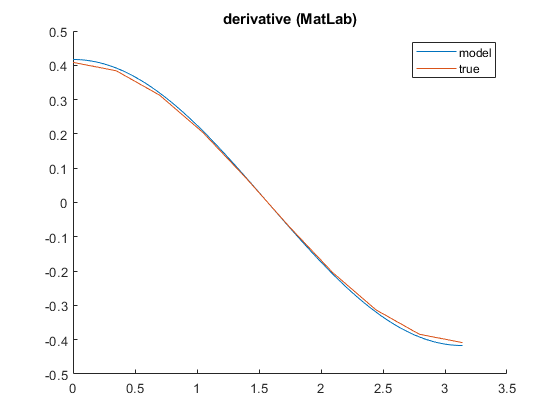


figure()
hold on
plot(xh,gradient(ypredml,xh(2)-xh(1)))
plot(x,gradient(y,x(2)-x(1)))
title('derivative (MatLab)')
legend('model','true')

figure()
hold on
scatter(x,y)
modelhm = fit_homemade_model(x,y,sigma,kfcn)

modelhm = function_handle with value:
    @(x_pred)kfcn(x_pred,x_train)*inv(kfcn(x_train,x_train)+sigma^2*eye(size(x_train,1),size(x_train,1)))*y_train


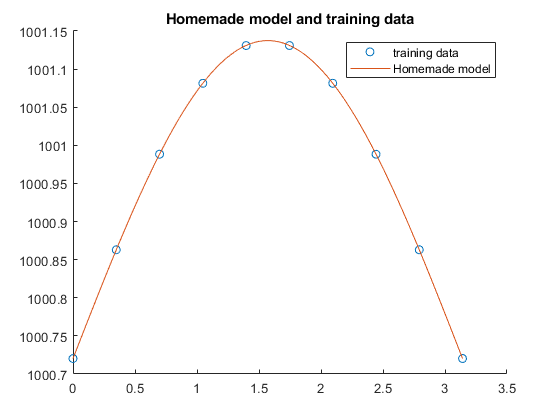

ypredhm = modelhm(xh);
plot(xh,ypredhm)
title('Homemade model and training data')
legend('training data','Homemade model')

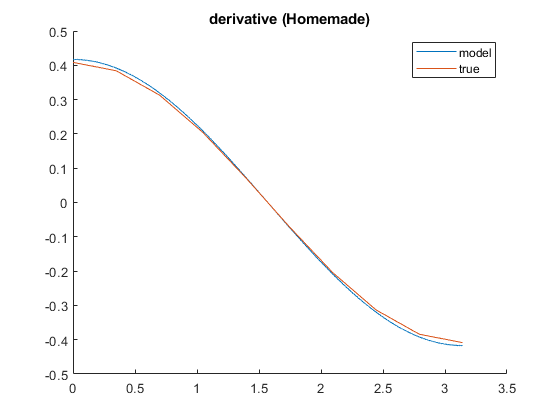


figure()
hold on
plot(xh,gradient(ypredhm,xh(2)-xh(1)))
plot(x,gradient(y,x(2)-x(1)))
title('derivative (Homemade)')
legend('model','true')

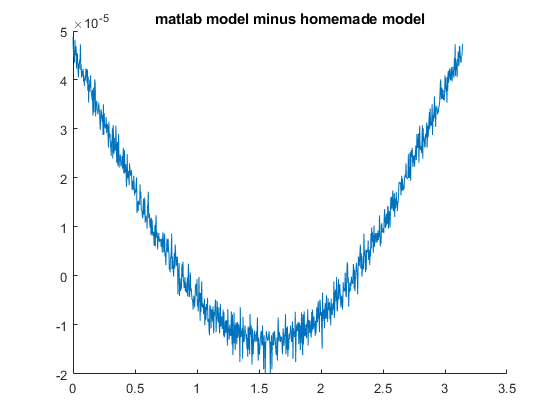


figure()
hold on
plot(xh,ypredml - ypredhm)
title('matlab model minus homemade model')

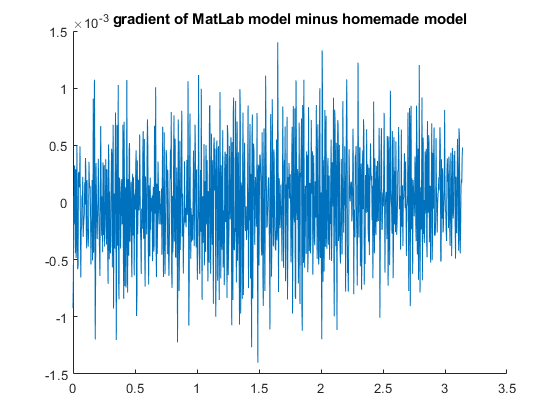


figure()
hold on
plot(xh,gradient(ypredml - ypredhm,xh(2)-xh(1)))
title('gradient of MatLab model minus homemade model')

function model = fit_matlab_model(x,y,sigma,kfcn)
    BasisFunction = 'Constant';
    model = fitrgp(x,y,...
        'Sigma',sigma,...
        'ConstantSigma',true,...
        'KernelFunction',kfcn,...
        'KernelParameters',0,...
        'FitMethod','exact');
end

function model = fit_homemade_model(x_train,y_train,sigma,kfcn)
    % This function is intended to facilitate making function handles. I.e.
    % call like model = @(x_pred)
    % create_model(x_pred,x_train,y_train,sigma);
    model = @(x_pred) kfcn(x_pred,x_train)*...
        inv(kfcn(x_train,x_train) + sigma^2*eye(size(x_train,1),size(x_train,1)))*...
        y_train;
end

function [kfcn,C] = get_kfcn(N_samp,N_res)
    for idx = 1:N_samp
        [x,y] = get_rand_data(N_res);
        ys(idx,:) = y;
    end
    C = cov(ys);
    kfcn = @(xi,xj,dummy) interp2(x,x',C,xi,xj')';
end

function [x,y] = get_rand_data(N_res)
    x = linspace(0,pi,N_res)';
    eps = 1e-2;
    y = rand*sin(x) + rand + 1000;
end

% function hfcn = get_hfcn()
%     hfcn = @(x) ones(size(x,1),1);
% end
